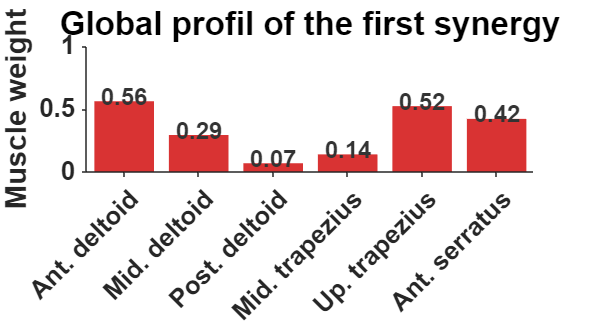

% Données
poids_synergie = JM13D_W1';
noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'Post. deltoid', ...
                'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};

% Création de la figure avec fond blanc
figure('Color', 'w');

% Barplot rouge sans bordure
b = bar(poids_synergie, 'FaceColor', [0.85 0.2 0.2], 'EdgeColor', 'none');
ylim([0 1]);
xlim([0.5 6.5]);

% Axe et ticks
set(gca, 'XTick', 1:6, ...
         'XTickLabel', noms_muscles, ...
         'FontSize', 14, ...
         'FontWeight', 'bold', ...
         'TickDir', 'out', ...
         'Box', 'off');

xtickangle(45);
ylabel('Muscle weight', 'FontSize', 16, 'FontWeight', 'bold');
title('Global profil of the first synergy', 'FontSize', 18, 'FontWeight', 'bold');

% Valeurs sur les barres
text(1:6, poids_synergie + 0.035, ...
     compose('%.2f', poids_synergie), ...
     'HorizontalAlignment', 'center', ...
     'FontSize', 13, ...
     'FontWeight', 'bold', ...
     'Color', [0.2 0.2 0.2]);

% Taille de la figure
set(gcf, 'Position', [100, 100, 900, 500]);

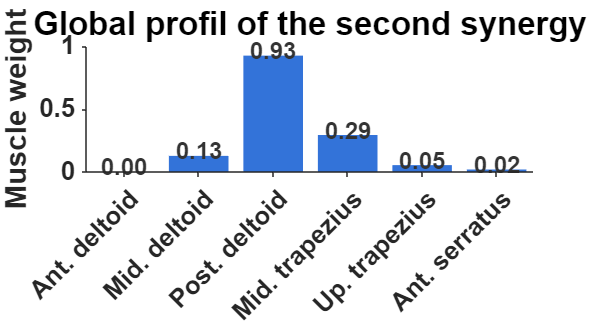

% Données synergie bleue
poids_synergie_2 = JM13D_W2';
noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'Post. deltoid', ...
                'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};

% Création de la figure avec fond blanc
figure('Color', 'w');

% Barplot bleu sans bordure
b = bar(poids_synergie_2, 'FaceColor', [0.2 0.45 0.85], 'EdgeColor', 'none');
ylim([0 1]);
xlim([0.5 6.5]);

% Axe et ticks
set(gca, 'XTick', 1:6, ...
         'XTickLabel', noms_muscles, ...
         'FontSize', 14, ...
         'FontWeight', 'bold', ...
         'TickDir', 'out', ...
         'Box', 'off');

xtickangle(45);
ylabel('Muscle weight', 'FontSize', 16, 'FontWeight', 'bold');
title('Global profil of the second synergy', 'FontSize', 18, 'FontWeight', 'bold');

% Valeurs sur les barres
text(1:6, poids_synergie_2 + 0.035, ...
     compose('%.2f', poids_synergie_2), ...
     'HorizontalAlignment', 'center', ...
     'FontSize', 13, ...
     'FontWeight', 'bold', ...
     'Color', [0.2 0.2 0.2]);

% Taille de la figure
set(gcf, 'Position', [100, 100, 900, 500]);

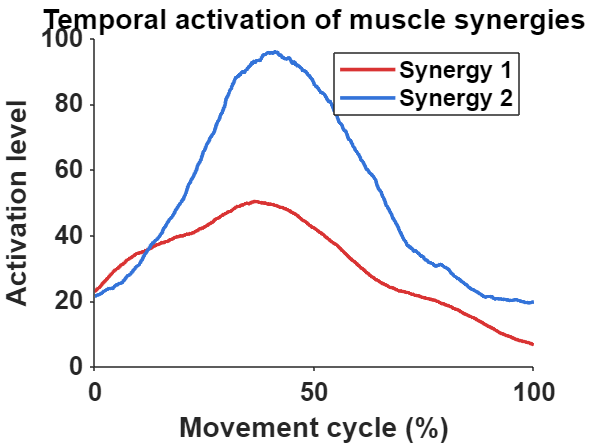

% Figure
figure('Color', 'w');

% Axe de 0 à 100 avec 1000 points
x = linspace(0, 100, length(YL03D_H1)); % axe de 0 à 100 avec 1000 points

% Tracé des synergies
plot(x, YL03D_H1, 'Color', [0.85 0.2 0.2], 'LineWidth', 2); hold on;
plot(x, YL03D_H2, 'Color', [0.2 0.45 0.85], 'LineWidth', 2);

% Esthétique
xlabel('Movement cycle (%)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('Activation level', 'FontSize', 16, 'FontWeight', 'bold');
title('Temporal activation of muscle synergies', 'FontSize', 18, 'FontWeight', 'bold');

legend({'Synergy 1', 'Synergy 2'}, ...
       'FontSize', 13, 'Location', 'northeast');

set(gca, 'FontSize', 14, ...
         'FontWeight', 'bold', ...
         'TickDir', 'out', ...
         'Box', 'off', ...
         'XLim', [0 100]);